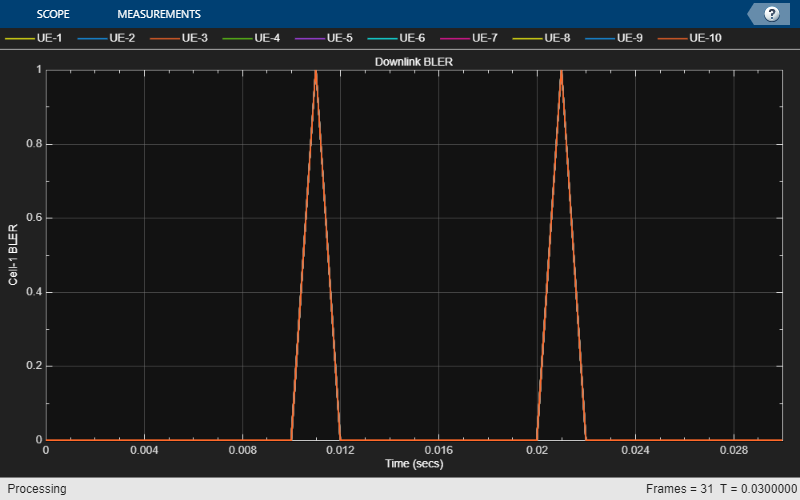

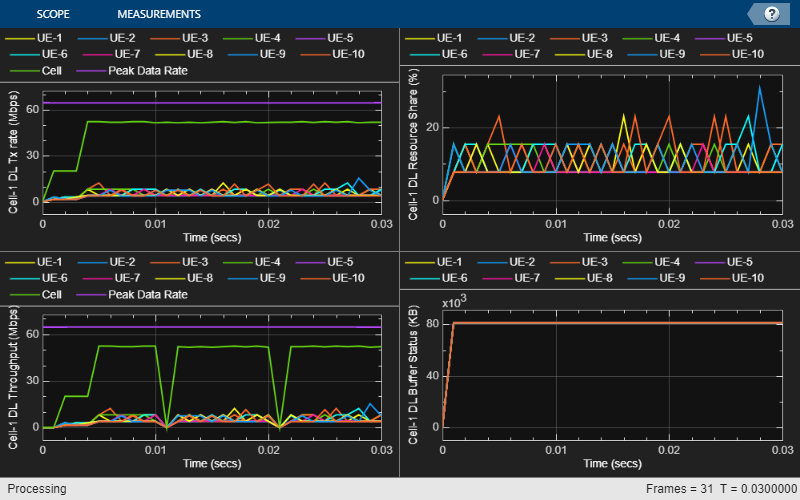

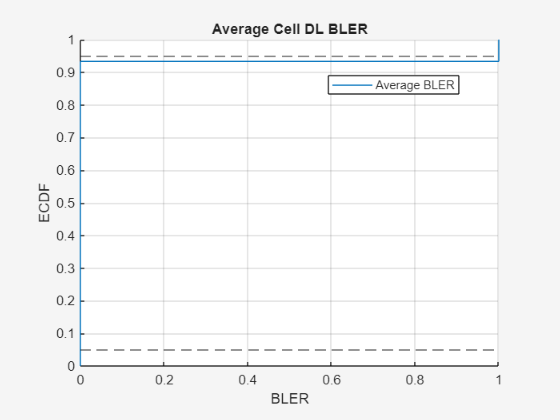

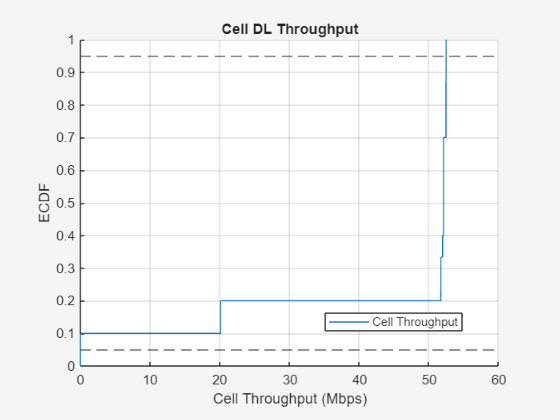

wirelessnetworkSupportPackageCheck
rng("default")          % Reset the random number generator
numFrameSimulation = 3; % Simulation time in terms of number of 10 ms frames
networkSimulator = wirelessNetworkSimulator.init;
gNBPosition = [0 0 0]; % [x y z] meters position in Cartesian coordinates
gNB = nrGNB(Position=gNBPosition,TransmitPower=34,SubcarrierSpacing=15000, ...
    CarrierFrequency=6e9,ChannelBandwidth=10e6,NumTransmitAntennas=32,ReceiveGain=17.5);
numUEs = 10; % Set the number of UEs
muMIMODLConfig = struct(MaxNumUsersPaired=4,MinNumRBs=2,SemiOrthogonalityFactor=1.0, ...
    MinCQI=10);
configureScheduler(gNB,ResourceAllocationType=0,MaxNumUsersPerTTI=10, ...
    MUMIMOConfigDL=muMIMODLConfig);
% For all UEs, specify position in spherical coordinates (r,azimuth,elevation)
% relative to gNB.
ueRelPosition = [ones(numUEs,1)*500 (rand(numUEs,1)-0.5)*120 zeros(numUEs,1)];
% Convert spherical to Cartesian coordinates considering gNB position as origin
[xPos,yPos,zPos] = sph2cart(deg2rad(ueRelPosition(:,2)),deg2rad(ueRelPosition(:,3)), ...
    ueRelPosition(:,1));
% Convert to absolute Cartesian coordinates
uePositions = [xPos yPos zPos] + gNBPosition;
ueNames = "UE-" + (1:size(uePositions,1));
UEs = nrUE(Name=ueNames,Position=uePositions,ReceiveGain=0,NumReceiveAntennas=1);
connectUE(gNB,UEs,FullBufferTraffic="DL")
addNodes(networkSimulator,gNB)
addNodes(networkSimulator,UEs)
channelConfig = struct("DelayProfile","CDL-D","DelaySpread",100e-9);
channels = createMultiUserCDLChannels(channelConfig,gNB,UEs);
customChannelModel = hNRCustomChannelModel(channels);
addChannelModel(networkSimulator,@customChannelModel.applyChannelModel)
enableTraces = true;
if enableTraces
    % Create an object for scheduler trace logging
    simSchedulingLogger = helperNRSchedulingLogger(numFrameSimulation,gNB,UEs);
    % Create an object for PHY trace logging
    simPhyLogger = helperNRPhyLogger(numFrameSimulation,gNB,UEs);
end
% This parameter has an impact on simulation time.
numMetricsSteps = 10*numFrameSimulation;
metricsVisualizer = helperNRMetricsVisualizer(gNB,UEs,NumMetricsSteps=numMetricsSteps, ...
    PlotSchedulerMetrics=true,PlotPhyMetrics=true,PlotCDFMetrics=true,LinkDirection=0);
simulationLogFile = "simulationLogs"; % For logging the simulation traces
% Calculate the simulation duration (in seconds)
simulationTime = numFrameSimulation*1e-2;
% Run the simulation
run(networkSimulator,simulationTime)

% Read performance metrics
displayPerformanceIndicators(metricsVisualizer)

Peak DL Throughput: 64.70 Mbps. Achieved Cell DL Throughput: 43.72 Mbps
Achieved DL Throughput for each UE: [4.99        3.51        5.12         4.3        3.76         4.9        3.84         4.3        4.77        4.22]
Peak DL spectral efficiency: 6.47 bits/s/Hz. Achieved DL spectral efficiency for cell: 4.37 bits/s/Hz
Block error rate for each UE in the downlink direction: [0.069       0.069       0.069       0.069       0.069       0.069       0.069       0.069       0.069       0.069]



if enableTraces
    simulationLogs = cell(1,1);
    if gNB.DuplexMode == "FDD"
        logInfo = struct("DLTimeStepLogs",[],"ULTimeStepLogs",[], ...
            "SchedulingAssignmentLogs",[],"PhyReceptionLogs",[]);
        [logInfo.DLTimeStepLogs,logInfo.ULTimeStepLogs] = getSchedulingLogs(simSchedulingLogger);
    else % TDD
        logInfo = struct("TimeStepLogs",[],"SchedulingAssignmentLogs",[],"PhyReceptionLogs",[]);
        logInfo.TimeStepLogs = getSchedulingLogs(simSchedulingLogger);
    end
    % Get the scheduling assignments log
    logInfo.SchedulingAssignmentLogs = getGrantLogs(simSchedulingLogger);
    % Get the PHY reception logs
    logInfo.PhyReceptionLogs = getReceptionLogs(simPhyLogger);
    % Save simulation logs in a MAT-file
    simulationLogs{1} = logInfo;
    save(simulationLogFile,"simulationLogs")
end

function channels = createMultiUserCDLChannels(channelConfig,gNB,UEs)
    numUEs = length(UEs);
    numNodes = length(gNB) + numUEs;
    channels = cell(numNodes,numNodes);

    waveformInfo = nrOFDMInfo(gNB.NumResourceBlocks,gNB.SubcarrierSpacing/1e3);
    sampleRate = waveformInfo.SampleRate;

    % Create a CDL channel model object configured with the desired delay
    % profile, delay spread, and Doppler frequency
    channel = nrCDLChannel;
    channel.CarrierFrequency = gNB.CarrierFrequency;
    % Delay profile. You can configure it as CDL- A,B,C,D,E
    channel.DelayProfile = channelConfig.DelayProfile;
    channel.DelaySpread = channelConfig.DelaySpread; % Delay Spread
    % Configure antenna down-tilt as 12 (degrees)
    channel.TransmitArrayOrientation = [0 12 0]';
    channel.SampleRate = sampleRate;
    channel.ChannelFiltering = false;

    % For each UE set DL channel instance
    for ueIdx = 1:numUEs

        % Create a copy of the original channel
        cdl = hMakeCustomCDL(channel);

        % Configure the channel seed based on the UE number
        % (results in independent fading for each UE)
        cdl.Seed = 73 + (ueIdx - 1);

        % Set antenna panel
        cdl = hArrayGeometry(cdl,gNB.NumTransmitAntennas,UEs(ueIdx). ...
            NumReceiveAntennas,"downlink");

        % Compute the LOS angle from gNB to UE
        [~,depAngle] = rangeangle(UEs(ueIdx).Position', ...
            gNB.Position');

        % Configure the azimuth and zenith angle offsets for this UE
        cdl.AnglesAoD(:) = cdl.AnglesAoD(:) + depAngle(1);
        % Convert elevation angle to zenith angle
        cdl.AnglesZoD(:) = cdl.AnglesZoD(:) - cdl.AnglesZoD(1) + (90 - depAngle(2));

        channels{gNB.ID,UEs(ueIdx).ID} = cdl;
    end
end